# Lab Activity 

#### ### Carson Batchelor ###

### fMRI reference waveform

This waveform is used to identify the period of the task so that other pixels associated with the task may be identified.

## Prepare Workspace

clear
close all

% load 122 x 1 reference signal waveform 

load fmrisig.mat

## Item 6 (i): Plot reference signal 

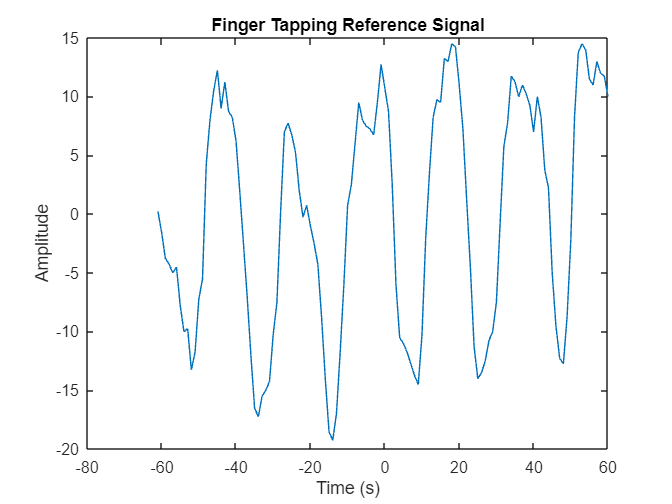

N = length(s);
fs = 4;

% Complete the following line and Uncomment to Run
t = (-N/2 : (N/2)-1);  %<=== complete this line
length(t);


figure
plot(t,s)
title('Finger Tapping Reference Signal')
ylabel('Amplitude')
xlabel('Time (s)')

## Item 6 (ii): Plot Spectrum

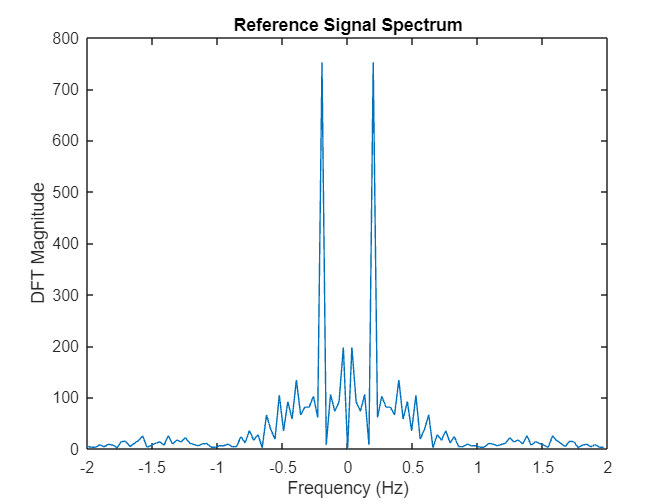

% Plot magnitude of DFT of reference
% Complete the following line of Code and Uncomment to Run
%f_hz = (fs*t)/N; %<=== complete this line
f_hz = (-N/2 : (N/2)-1) * fs/N;
S = fft(s); % Compute fft of time signal
S_shift = fftshift(S); % Shift zero-frequency component to center of spectrum


figure
plot(f_hz, abs(S_shift))
title('Reference Signal Spectrum')
xlabel('Frequency (Hz)')
ylabel('DFT Magnitude')


% Write code to find the index of Vector S corresponding to dominant
% positive frequency
    % Hint 1: look up the max function - it may be useful.
    % Hint 2: Question is asking the index for vector S but we are plotting
    % magnitude for S_Shift

[m,i] = max(S_shift)

m = 3.3338e+02 + 6.7398e+02i

i = 68

find(S == max(S_shift))

ans = 7

## Item 7: Generate sinusoid approximation

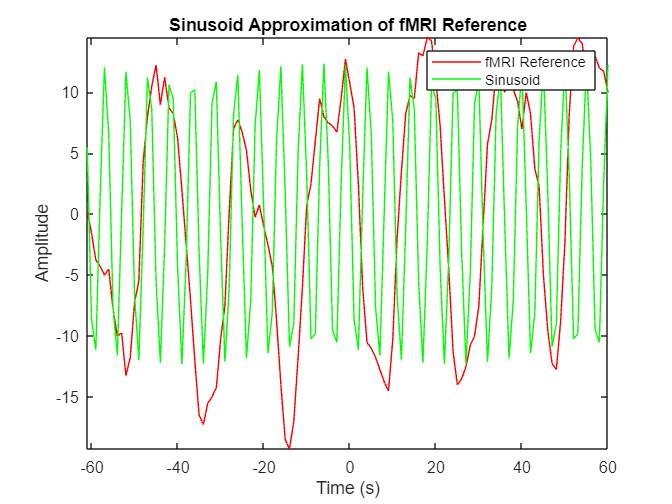

% Complete the following lines of Code and Uncomment to Run
f = (6/122) * 4; %<=== complete this line
A = (2/122) * 751.928; %<=== complete this line
phi = 1.1114; %<=== complete this line

s_hat = A*cos(2*pi*f*t+phi);

figure
plot(t,s,'r',t,s_hat,'g')
legend('fMRI Reference','Sinusoid')
xlabel('Time (s)')
ylabel('Amplitude')
title('Sinusoid Approximation of fMRI Reference')
axis('tight')